clc;
close all;
clear;
load("robot.mat");

### strategy:

#### position 1:     0    253.3    67.8          

#### position 2:    0    247.3    48.5  

#### ----------------pump on----------------

#### position 3:   0    247.3    48.5    

#### position 4:     0    289.2    76.0   

#### position 5:   0    289.2    76.0  

#### ----------------pump off----------------

#### position 6:   0    289.2    76.0     

%calculate joint angle
target_points = [       0    253.3    67.8;
                        0    247.3    48.5;
                        0    256.1    79.6;
                        0    286.6    60.7;
                        0    283.8    53.5;
                        0    289.2    76.0];
target_points = target_points / 1000;

ik = inverseKinematics('RigidBodyTree', robot);
weights = [0.01 0.01 0.01 0.1 0.1 0.1]; 
endEffectorName = 'arm6';
% ik
calculated_theta_list = zeros(size(target_points, 1), length(robot.homeConfiguration));
for i = 1:size(target_points, 1)
    targetPosition = target_points(i, :);
    targetPose = trvec2tform(targetPosition); 
    [solution, solnInfo] = ik(endEffectorName, targetPose, weights, robot.homeConfiguration);
    if solnInfo.ExitFlag > 0
        calculated_theta_list(i, :) = rad2deg(solution); 
    else
        disp(['IK solution not found for position ', num2str(i)]);
    end
end

disp('Calculated joint angles using Inverse Kinematics:');

Calculated joint angles using Inverse Kinematics:



% correct the format
calculated_theta_list = calculated_theta_list';
disp(calculated_theta_list); %show

   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000
  -36.3213  -32.2443  -38.7222  -15.5736  -15.0601  -18.5263
  -11.1260   -9.5909  -12.0831  -42.8225  -40.9749  -43.5413
   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
   47.4473   41.8352   50.8053   58.3962   56.0350   62.0677
  -90.0000  -90.0000  -90.0000  -90.0000  -90.0000  -90.0000



calculated_theta_list = calculated_theta_list*pi/180; % use rad in matlab
calculated_theta_list(6,:) = 0; % keep zero
num_joint_angle = size(calculated_theta_list,2); % joint angle nums

Step = 30;
tip_positions = zeros([Step*num_joint_angle,3]);
total_steps = Step * num_joint_angle;
num_joints = 6;

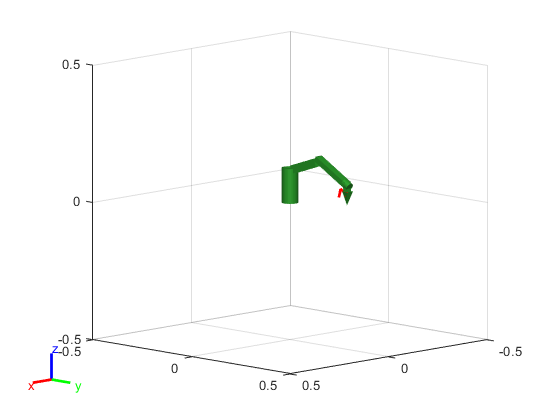

fig = figure('Color', [1 1 1]);
ax = axes('Parent', fig, 'DataAspectRatio', [1 1 1], 'XLim', [-0.5 0.5], 'YLim', [-0.5 0.5], 'ZLim', [-0.5 0.5]);
set(ax, 'XDir','reverse', 'YDir','reverse', 'ZDir','normal');
lighting gouraud;
light('Position',[1 1 1],'Style','infinite');
material dull;  
view(3);
view(ax, -45, 10);
grid on;
hold(ax, 'on');
zoom on;
pan on;
robotPlot = show(robot, calculated_theta_list(:,1), 'Parent', ax, 'PreservePlot', false);
trajectoryPlot = plot3(ax, NaN, NaN, NaN, 'r', 'LineWidth', 2);

v = VideoWriter('Task4.avi');
v.FrameRate = 15;
open(v);
for j = 2:num_joint_angle 
    Qd = calculated_theta_list(:,j)-calculated_theta_list(:,j-1);
    idx = (j-2)*Step;
    for i = 1:Step
        q = calculated_theta_list(:,j-1) + Qd / Step * i;
        tip_positions(i+idx,:) = cal_tip_positions(q);
        show(robot, q, 'Parent', ax, 'PreservePlot', false, "Collisions","on","Frames","off");
        set(trajectoryPlot, 'XData', tip_positions(1:i+idx, 1), 'YData', tip_positions(1:i+idx, 2), 'ZData', tip_positions(1:i+idx, 3));
        drawnow;

        frame = getframe(gcf);
        writeVideo(v, frame);
    end
end
hold(ax, 'off');

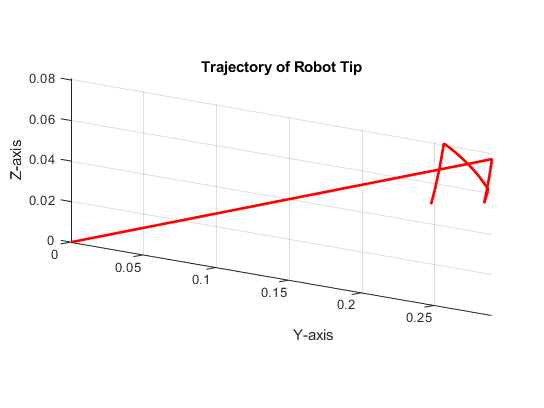

close(v);
figure('Color', [1 1 1]);
plot3(tip_positions(:, 1), tip_positions(:, 2), tip_positions(:, 3), 'r', 'LineWidth', 2);
grid on;
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('Trajectory of Robot Tip');
axis equal;
view(135, 10); 

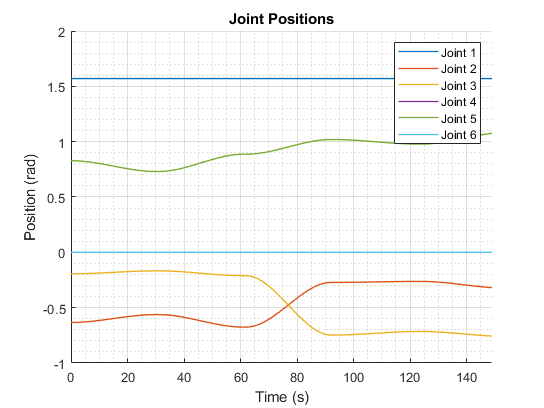

joint_positions = [];
joint_velocities = [];
for i = 1:num_joints
    for j = 2:num_joint_angle 
        [pos, vel] = calculateJointMotion(calculated_theta_list(:,j-1), calculated_theta_list(:,j), Step);
        joint_positions = [joint_positions, pos];
        joint_velocities = [joint_velocities, vel];
    end  
end

t = 0:(size(joint_positions, 2) - 1);
figure('Color', [1 1 1]);
hold on;
grid on;
grid minor;
for i = 1:num_joints
    plot(t, joint_positions(i,:), 'LineWidth', 1, 'DisplayName', ['Joint ' num2str(i)]);
end
xlim([0, (num_joint_angle-1)*Step - 1]);
title("Joint Positions");
xlabel("Time (s)");
ylabel("Position (rad)");
legend;

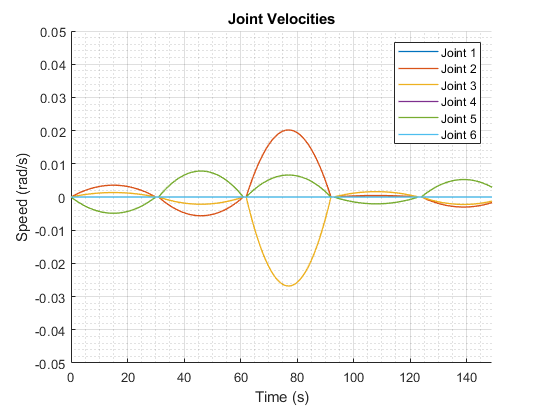


figure('Color', [1 1 1]);
hold on;
grid on;
grid minor;
for i = 1:num_joints
    plot(t, joint_velocities(i,:), 'LineWidth', 1, 'DisplayName', ['Joint ' num2str(i)]);
end
xlim([0, (num_joint_angle-1)*Step - 1]);
ylim([-0.05,0.05]);
title("Joint Velocities");
xlabel("Time (s)");
ylabel("Speed (rad/s)");
legend;

Task4_theta_list = calculated_theta_list;
Task4_theta_list(2,:) = Task4_theta_list(2,:) + pi/2;
Task4_theta_list(5,:) = Task4_theta_list(5,:) - pi/2;
Task4_theta_list*180/pi

ans =    90.0000   90.0000   90.0000   90.0000   90.0000   90.0000
   53.6787   57.7557   51.2778   74.4264   74.9399   71.4737
  -11.1260   -9.5909  -12.0831  -42.8225  -40.9749  -43.5413
   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
  -42.5527  -48.1648  -39.1947  -31.6038  -33.9650  -27.9323
         0         0         0         0         0         0


save("Task4_theta_list.mat","Task4_theta_list");